clear; clc;

## Problem 3 Levenberg-Marquardt

% DERIVING GRADIENTS
syms x_1 x_2
% f_sym = (1-x_1)^2 + 100*(x_2-x_1^2)^2;
u = (1/2)*(x_1^2 + x_2^2 - 25);
f_sym = exp(u^2) + sin(4*x_1 - 3*x_2)^4 + 0.5*(2*x_1 + x_2 - 10)^2

$$f\_sym = {\mathrm{e}}^{{\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{25}{2}\right)}^{2}}+\frac{{\left(2\,x_{1}+x_{2}-10\right)}^{2}}{2}+{\sin\left(4\,x_{1}-3\,x_{2}\right)}^{4}$$

f = matlabFunction(f_sym); f = @(x) f(x(1), x(2));

grad = [diff(f_sym, x_1); diff(f_sym, x_2)]

$$grad = \begin{array}{l} \left(\begin{array}{c} 16\,\cos\left(4\,x_{1}-3\,x_{2}\right)\,\sigma_{2}+4\,x_{1}+2\,x_{2}+2\,x_{1}\,{\mathrm{e}}^{{\sigma_{1}}^{2}}\,\sigma_{1}-20\\ -12\,\cos\left(4\,x_{1}-3\,x_{2}\right)\,\sigma_{2}+2\,x_{1}+x_{2}+2\,x_{2}\,{\mathrm{e}}^{{\sigma_{1}}^{2}}\,\sigma_{1}-10 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{25}{2}\\ \sigma_{2}={\sin\left(4\,x_{1}-3\,x_{2}\right)}^{3} \end{array}$$

f_grad = matlabFunction(grad); f_grad = @(x) f_grad(x(1), x(2));

grad = [diff(grad(1), x_1) diff(grad(1), x_2);
        diff(grad(2), x_1) diff(grad(2), x_2)]

$$grad = \begin{array}{l} \left(\begin{array}{cc} 192\,\sigma_{5}\,\sigma_{4}+\sigma_{2}+2\,{x_{1}}^{2}\,{\mathrm{e}}^{\sigma_{6}}-64\,\sigma_{3}+4\,{x_{1}}^{2}\,{\mathrm{e}}^{\sigma_{6}}\,\sigma_{6}+4 & \sigma_{1}\\ \sigma_{1} & 108\,\sigma_{5}\,\sigma_{4}+\sigma_{2}+2\,{x_{2}}^{2}\,{\mathrm{e}}^{\sigma_{6}}-36\,\sigma_{3}+4\,{x_{2}}^{2}\,{\mathrm{e}}^{\sigma_{6}}\,\sigma_{6}+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=48\,\sigma_{3}-144\,\sigma_{5}\,\sigma_{4}+2\,x_{1}\,x_{2}\,{\mathrm{e}}^{\sigma_{6}}+4\,x_{1}\,x_{2}\,{\mathrm{e}}^{\sigma_{6}}\,\sigma_{6}+2\\ \sigma_{2}=2\,{\mathrm{e}}^{\sigma_{6}}\,\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{25}{2}\right)\\ \sigma_{3}={\sin\left(4\,x_{1}-3\,x_{2}\right)}^{4}\\ \sigma_{4}={\sin\left(4\,x_{1}-3\,x_{2}\right)}^{2}\\ \sigma_{5}={\cos\left(4\,x_{1}-3\,x_{2}\right)}^{2}\\ \sigma_{6}={\left(\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}-\frac{25}{2}\right)}^{2} \end{array}$$

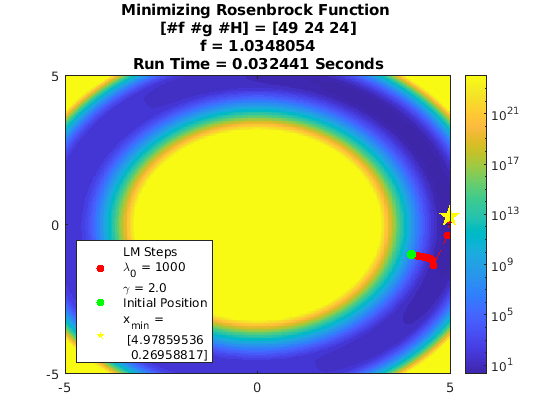

f_grad2 = matlabFunction(grad); f_grad2 = @(x) f_grad2(x(1), x(2));

% SETUP
x0 = [4; -1]; x = x0;
% x0 = [2; 3]; x = x0;
xout = x0;
dx = Inf;
fCalls = [0 0 0];
t0 = 0.1;
iters = 0;
tic
filename = 'hw3p3_4LM.png';

% START CONDITIONS
lambda = 1e3; gamma = 2;
lambdaList = lambda;
J = f(x); Jlast = J;
g = f_grad(x);
H = f_grad2(x);
fCalls = fCalls + [1 1 1];
lamMin = min(eig(H));

% ITERATING
while ~(norm(g) < 1e-8 && lamMin > 0)
    
    % FINDING TEST POINT
    xtest = x + (H + lambda*eye(length(x))) \ -g;
    
    % TESTING
    J = f(xtest);
    fCalls(1) = fCalls(1) + 1;
    if J > Jlast
        lambda = lambda*gamma;
%         if lambda < 1 || lambda > 1e12; break; end
        iters = iters + 1;

        if iters == 1000; break; else; continue; end
    end
    
    % ACCEPTING STEP
    x = xtest;
    Jlast = J;
    lambda = lambda / gamma^2;
    
%     UPDATING GRADIENTS
%     J = f(x);
    g = f_grad(x);
    H = f_grad2(x);
    fCalls = fCalls + [0 1 1];
    lamMin = min(eig(H));
    xout = cat(2, xout, x);
    
%     lambda = max(max(-lamMin + 1e-8, 1e3), lambda);
    
    iters = iters+1;
    lambdaList(end+1) = lambda;
    if iters == 1000; break; end
end
time = toc;

% PLOTTING
x1_space = -5:0.1:5;
x2_space = -5:0.1:5;
z_space = zeros(length(x1_space));
for i = 1:length(x1_space)
    for j = 1:length(x1_space)
        z_space(j, i) = f([x1_space(i), x2_space(j)]); 
    end
end
time = toc;

% Contour
contourf(x1_space, x2_space, z_space, [logspace(0, 24, 40)], ...
    'HandleVisibility',"off", 'LineStyle',"none")
hold on
set(gca, 'ColorScale', 'log');
caxis([2, 1e24])
scatter(xout(1, :), xout(2, :), 'ro', 'filled', 'DisplayName', ...
    ['LM Steps', newline, '\lambda_0 = ', sprintf('%0.6g', lambdaList(1)), newline, '\gamma = ', sprintf('%0.1f', gamma)])
plot(xout(1, :), xout(2, :), 'r--', 'HandleVisibility',"off")
scatter(xout(1, 1), xout(2, 1), 50, 'go', 'filled', 'DisplayName',"Initial Position")
C = colorbar('peer', gca, "eastoutside", 'Ticks', logspace(1, 25, 7));
scatter(x(1, end), x(2, end), 300, 'yp', 'filled', 'DisplayName', sprintf('x_{min} =\n [%0.8f\n  %0.8f]', x(1, end), x(2, end)))
hold off
legend('Location', 'southwest')
title(sprintf('Minimizing Rosenbrock Function \n[#f #g #H] = [%i %i %i]\nf = %0.8g\nRun Time = %0.6f Seconds', fCalls(1), fCalls(2), fCalls(3), f(x), time))
exportgraphics(gcf, filename, 'Resolution', 200);